# Time Series forecasting using LSTM

This example shows how to forecast time-series data using a long short-term memory (LSTM) network.

To forecast the values of future time steps of a sequence, you can train a sequence-to-sequence regression LSTM network, where the responses are the training sequences with values shifted by one time step. That is, at each time step of the input sequence, the LSTM network learns to predict the value of the next time step.

This example uses the data set `chickenpox_dataset`. This example trains an LSTM network to forecast the number of chickenpox cases given the number of cases in previous months. The training data contains a single time series, with time steps corresponding to months and values corresponding to the number of cases.

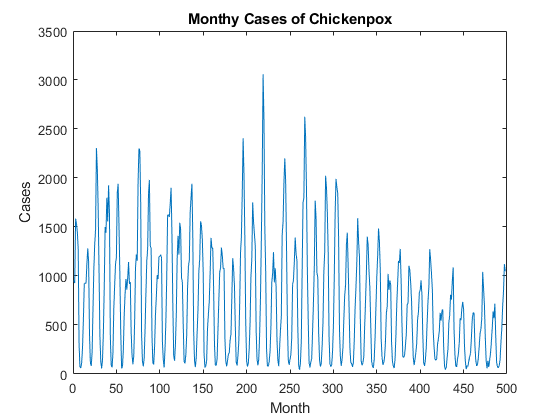

data = chickenpox_dataset;
data = [data{:}];

figure
plot(data)
xlabel("Month")
ylabel("Cases")
title("Monthy Cases of Chickenpox")

Partition training and test data. Train on the first 90% of the sequence and test on the last 10%.

To forecast the values of future time steps of a sequence, specify the responses to be the training sequences with values shifted by one time step. That is, at each time step of the input sequence, the LSTM network learns to predict the value of the next time step.

sequenceLength = floor(0.9*numel(data));
XTrain = data(1:sequenceLength);
YTrain = data(2:sequenceLength+1);
XTest = data(sequenceLength+1:end-1);
YTest = data(sequenceLength+2:end);

For better a better fit and to prevent the training from diverging, normalize the training data to have zero mean and unit variance. Normalize the test data using the same normalization parameters as the training data.

mu = mean(XTrain);
sig = std(XTrain);

XTrain = (XTrain - mu) / sig;
YTrain = (YTrain - mu) / sig;

XTest = (XTest - mu) / sig;

Create LSTM regression network. Specify the LSTM layer to have 200 hidden units. Then, specify the training options. Set the solver to be `'adam'` and train for 250 epochs. To prevent the gradients from exploding, set the gradient threshold to be 1. Specify the initial learn rate to be 0.005 and drop the learn rate after 125 epochs by multiplying by a factor of 0.2. Then, train the LSTM network with the specified training options.

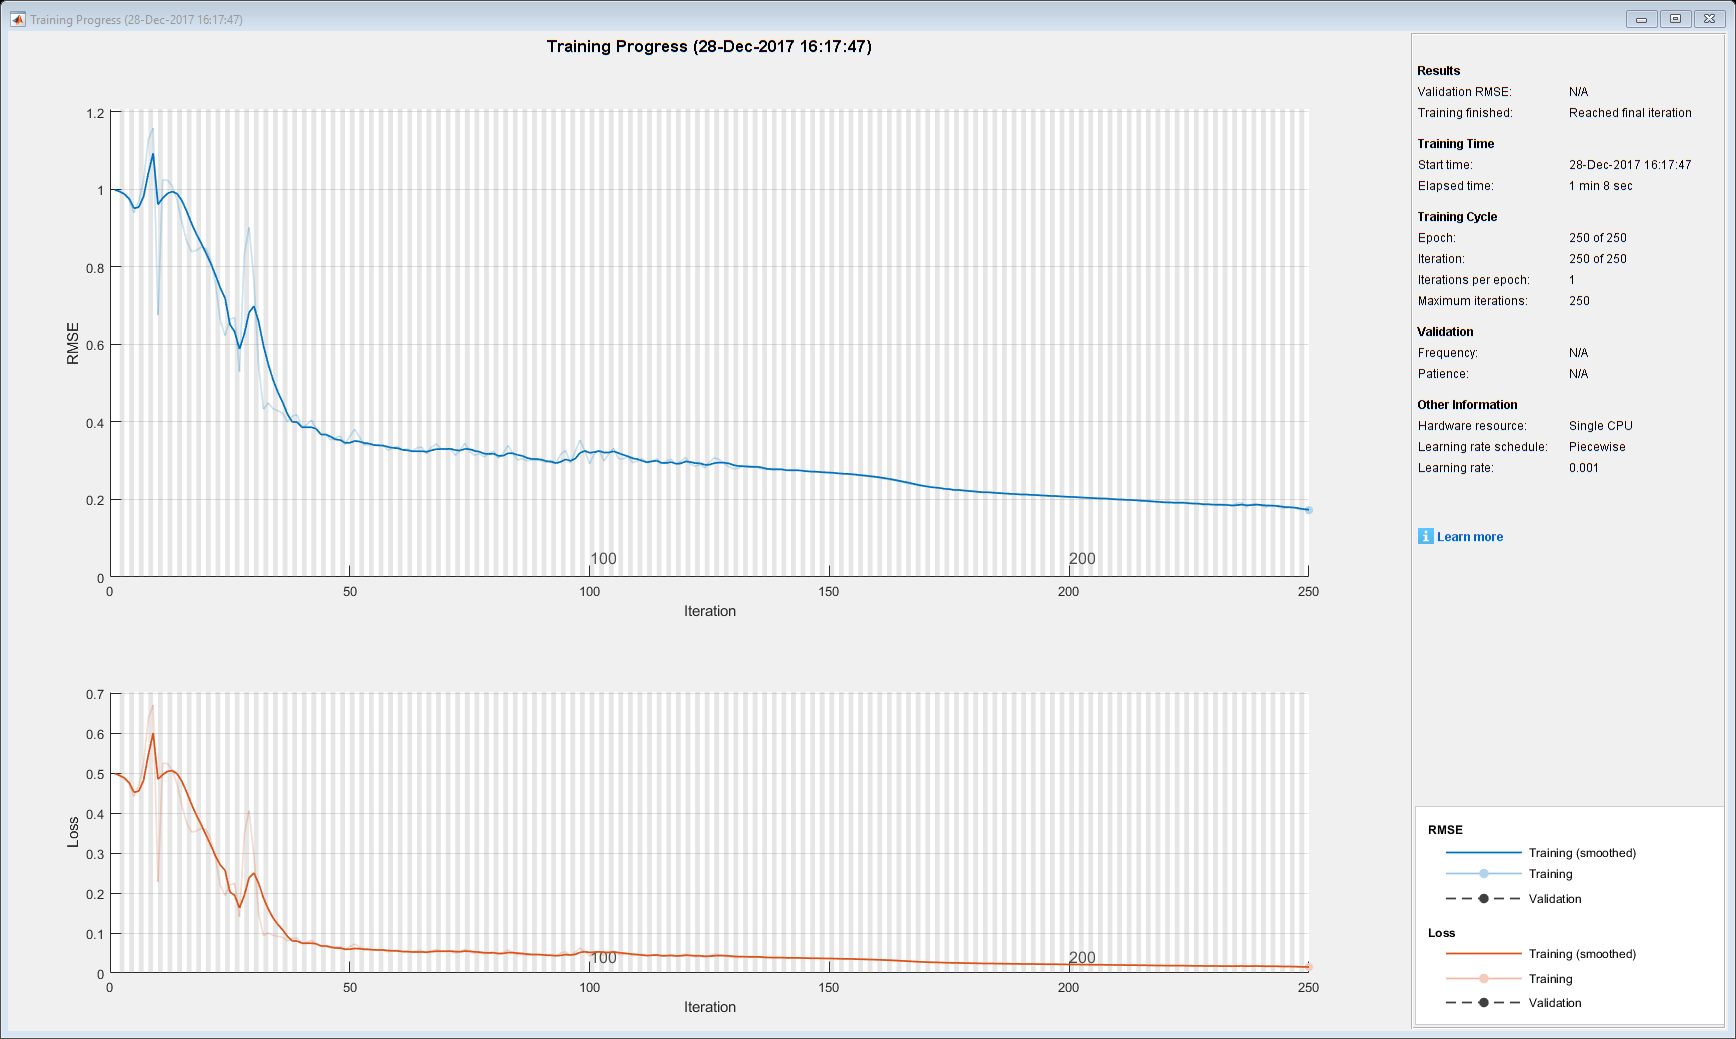

inputSize = 1;
numResponses = 1;
numHiddenUnits = 200;

layers = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];

opts = trainingOptions('adam', ...
    'MaxEpochs',250, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress');

net = trainNetwork(XTrain,YTrain,layers,opts);

To forecast the values of multiple time steps in the future, use the `predictAndUpdateState` function to predict time steps one at a time and update the network state at each prediction. For each prediction, use the previous prediction as input to the function. Then, denormalize the predictions using `mu` and `sig` calculated earlier.

net = predictAndUpdateState(net,XTrain);
[net,YPred] = predictAndUpdateState(net,YTrain(end));

numPredictions = numel(XTest);
for i = 2:numPredictions
    [net,YPred(1,i)] = predictAndUpdateState(net,YPred(i-1));
end

YPred = sig*YPred + mu;

Compare the forecasted values with the test data.

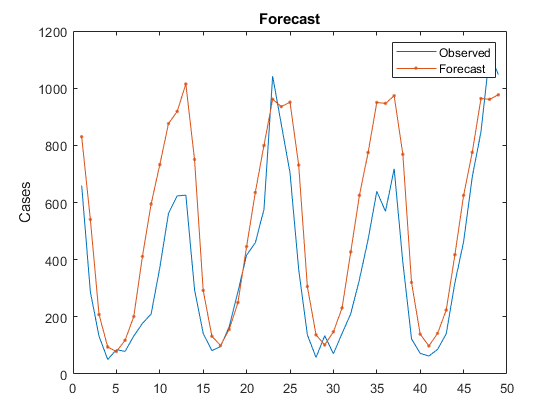

figure
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Forecast"])
ylabel("Cases")
title("Forecast")